# Result Analyze

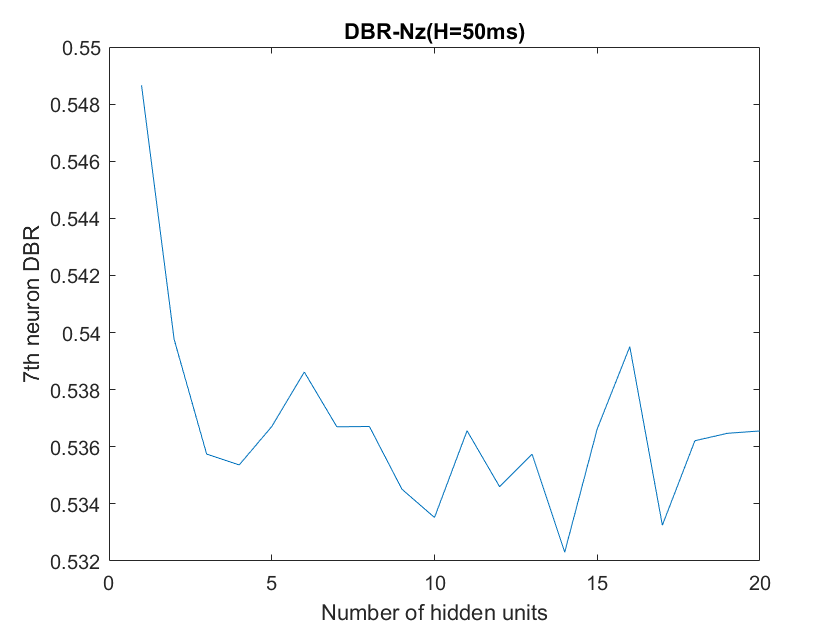

close all;clear;clc;
addpath models/
load data/rat_010_07_04_selected.mat
load results/GLM_explore_H.mat
load results/GLM_sec_explore_H.mat
load results/ANN_explore_Nz_more.mat

% ANN Nz-DBR
bestDBR = zeros(1, 20);
for i=1:20
  dbrList = zeros(1, 70);
  for j=1:70
    dbrList(j) = ANN_explore_Nz(i,j).DBR;
  end
  bestDBR(i) = min(dbrList);
end
figure(1)
plot(1:20, bestDBR)
xlabel("Number of hidden units")
ylabel("7th neuron DBR")
title("DBR-Nz(H=50ms)")

每一个Nz都随机初始化了70次，取DBR结果最好的一次绘图。期望应该是随着Nz变大DBR越来越好或基本不变，看起来Nz=5:8, 11:13,15:20附近的结果不是很好，more初始化or扩大初始化范围？

但任何Nz的最优结果DBR都小于GLM

取Nz=10来explore H应该是可行的

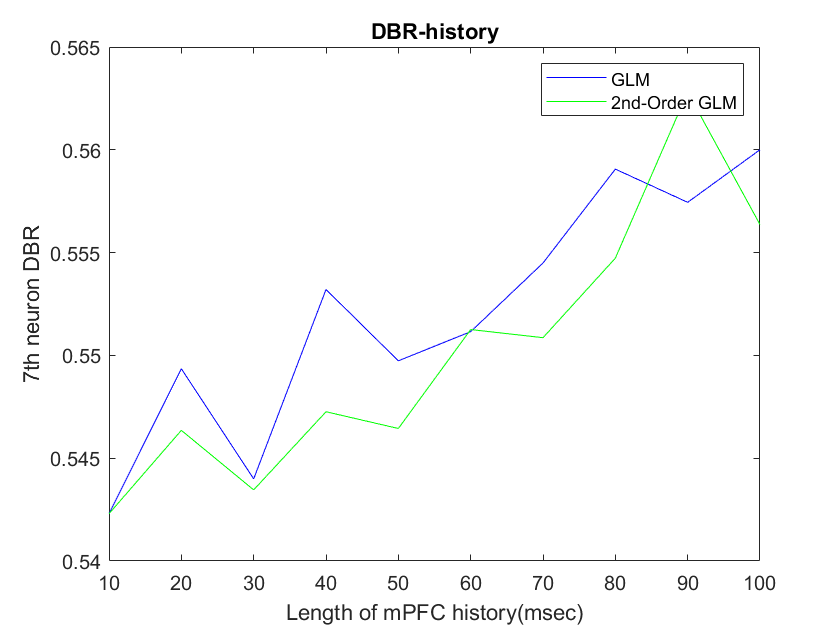

% get DBRs from differnt model result
GLM_sec_DBR = zeros(1,10);
GLM_DBR = zeros(1,10);
for i=1:10
  GLM_DBR(i)     = GLM_explore_H(i).DBR;
  GLM_sec_DBR(i) = GLM_sec_explore_H(i).DBR;
end
% plot DBR-history result
figure(2)
plot(10:10:100, GLM_DBR, 'b')
hold on
plot(10:10:100, GLM_sec_DBR, 'g')
hold off
legend("GLM", "2nd-Order GLM")
xlabel("Length of mPFC history(msec)")
xlim([10 100])
ylabel("7th neuron DBR")
title("DBR-history")

Take history = 50msec, kernel size = 0.6s

H = 5;
% get GLM params & test result
W     = GLM_explore_H(H).W;
M1Idx = GLM_explore_H(H).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
GLMtestLambdaYpre = GLMmodel(testX, W);
GLMccList = zeros(1, 1000/10);
% smooth result
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccList(kernelSize/10) = cc(2);
end

% 2nd Order GLM
W     = GLM_sec_explore_H(H).W;
M1Idx = GLM_sec_explore_H(H).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitDataSecOrder(mPFCspike,M1spike(:,M1Idx),H);
GLMsectestLambdaYpre = GLMmodel(testX, W);
GLM_sec_ccList = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccList(kernelSize/10) = cc(2);
end

% ANN
Nz=14;
bestDBR = 1;
for i=1:length(ANN_explore_Nz)
  if (ANN_explore_Nz(Nz,i).DBR < bestDBR)
    bestDBR = ANN_explore_Nz(Nz,i).DBR;
    W = ANN_explore_Nz(Nz,i).W;
  end
end
M1Idx = 1; % ANN_explore_Nz(H).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
[~, Nx] = size(testX);
ANNtestLambdaYpre = ANNmodel(testX, W, Nx, Nz);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in ANNmodel (line 13)
lambdaYpredict = sigmaFunc([lambdaZ, ones(length(lambdaZ), 1)]*theta');

ANNccList = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccList(kernelSize/10) = cc(2);
end

% optimal smooth kernel size result
kernelSize = 50;
smoothedLambda = gaussianSmooth(testY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);

% take part of result for display
t = 0.01:0.01:80;
index = 1:8000;
figure(3)
% real spike
subplot(4,1,2)
area(t, testY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
hold off
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccList, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccList, 'g')
plot(0.1:0.1:10, ANNccList, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", "Staged Point-Process Model", ...
  "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")
% legend([h{1}; h{2}; h{3}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
%   "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")
subplot(4,1,1)
area(t, eventTrain(index))

这几乎看不出来区别啊。。。取的H=5，Nz=14. DBR和cc的确略有优势，但是在图上看到的效果和人家论文里的完全不一样

尝试了不同的kernel size，但是始终没有观察到太多的区分

figure
hold on
for i=1:20*70
  LHistory = ANN_explore_Nz(i).LHistory;
  LHistory([false,LHistory(2:end)==LHistory(1)])=nan;
  h=plot(LHistory);
  set(h, 'color', [i/1400, i*i/(1400*1400), sqrt(i)/sqrt(1400)])
end
hold off

bestL = zeros(1, 20);
for i=1:20
  LvalList = zeros(1, 70);
  for j=1:70
    LvalList(j) = ANN_explore_Nz(i,j).Lval;
  end
  bestL(i) = max(LvalList);
end
plot(bestL)
bestDBR = zeros(1, 20);
for i=1:20
  dbrList = zeros(1, 70);
  for j=1:70
    dbrList(j) = ANN_explore_Nz(i,j).DBR;
  end
  bestDBR(i) = min(dbrList);
end
plot(bestDBR)